# Modelling the internal dipole moment of Ganymede

The following equation gives the permenant dipole moment of Ganymede in spherical polar coordinates.


$$U_{\mathrm{dipole}} =\left(B_G R_G^3 \right)\frac{\mathrm{cos}\;\theta }{r^2 }$$


This equation is expressed in terms of Cartesian coordinates as:


$$U_{\mathrm{dipole}\;} =\left(B_G R_G^3 \right)\frac{z}{{\left(x^2 +y^2 +z^2 \right)}^{\frac{3}{2}} }$$


The potential is differentiated with respect to the 3 coordinates to find the magnetic field strength in each direction.

$\mathit{\mathbf{B}}=-\frac{\;\partial U}{\partial \mathit{\mathbf{r}}}$ (general vector expression)


$$B_x =\left(3B_G R_G^3 \right)\frac{\mathrm{xz}}{{\left(x^2 +y^2 +z^2 \right)}^{\frac{5}{2}} }$$



$$B_y =\left(3B_G R_G^3 \right)\frac{\mathrm{yz}}{{\left(x^2 +y^2 +z^2 \right)}^{\frac{5}{2}} }\;$$



$$B_z =\frac{-B_G R_G }{{\left(x^2 +y^2 +z^2 \right)}^{\frac{3}{2}} }+\left(3B_G R_G^3 \right)\frac{z^2 }{{\left(x^2 +y^2 +z^2 \right)}^{\frac{5}{2}} }\;$$


A function is created to calculate the magnetic field formed by the permanent dipole moment of Ganymede. Ganymede is at the centre. 

Arrays of coordinates will be passed to the function to plot the magnetic field created by internal sources.

Firstly, we will plot the potential function using surf, then plot the magnetic field by streamline/quiver.

# G28 pass

g0 = -698;

% plotting U_xyz potential
x_arr_G = linspace(-5,5,100); 
y_arr_G = linspace(-5,5,100);
z_arr_G = linspace(-5,5,100);

[x3D_G,y3D_G,z3D_G] = meshgrid(x_arr_G,y_arr_G,z_arr_G);

potential_G = potential_xyz(x3D_G,y3D_G,z3D_G,g0);

### Plotting potentials for G28 pass at different 2D planes

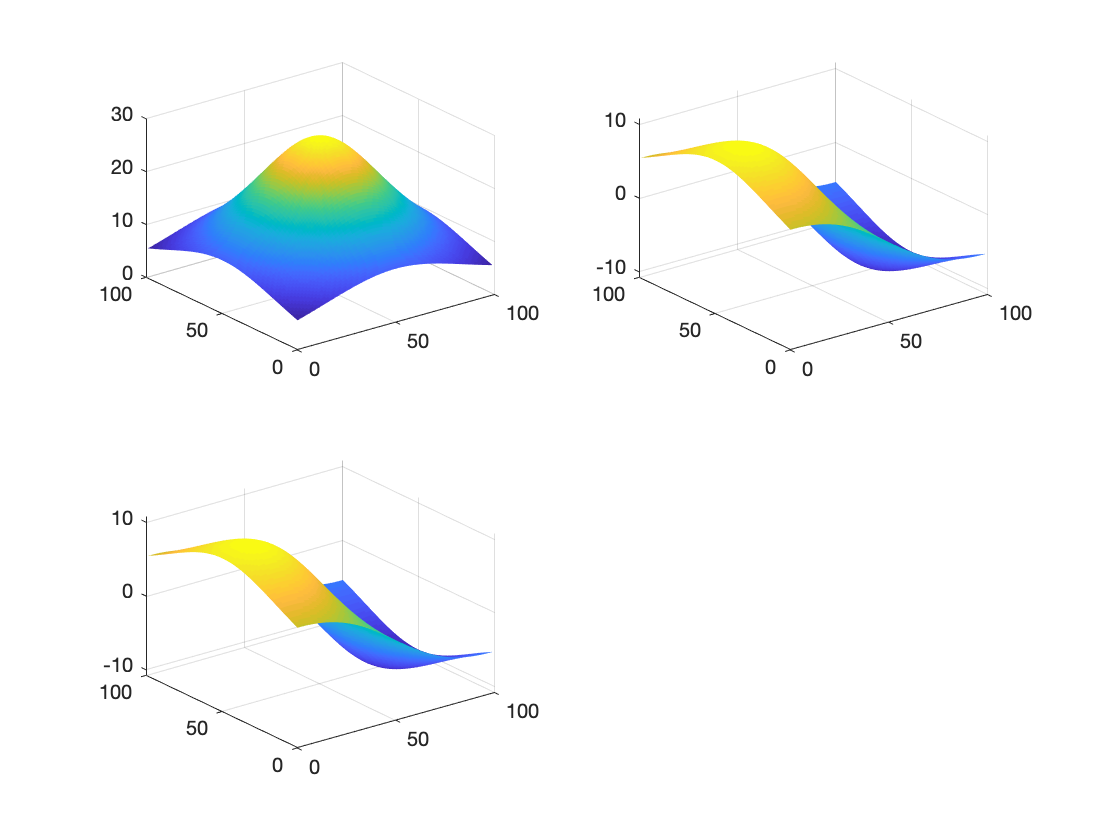

% potential at the edges of grid
figure;
% x-y plane 
subplot(2,2,1);
surf(potential_G(:,:,1))
shading flat
% x-z plane
subplot(2,2,2);
surf(squeeze(potential_G(:,1,:)))
shading flat
% y-z plane
subplot(2,2,3);
surf(squeeze(potential_G(1,:,:)))
shading flat

### Magnetic field due to dipole moment of Ganymede

(Explanation here)

### 2D pcolor plots - YZ Plane

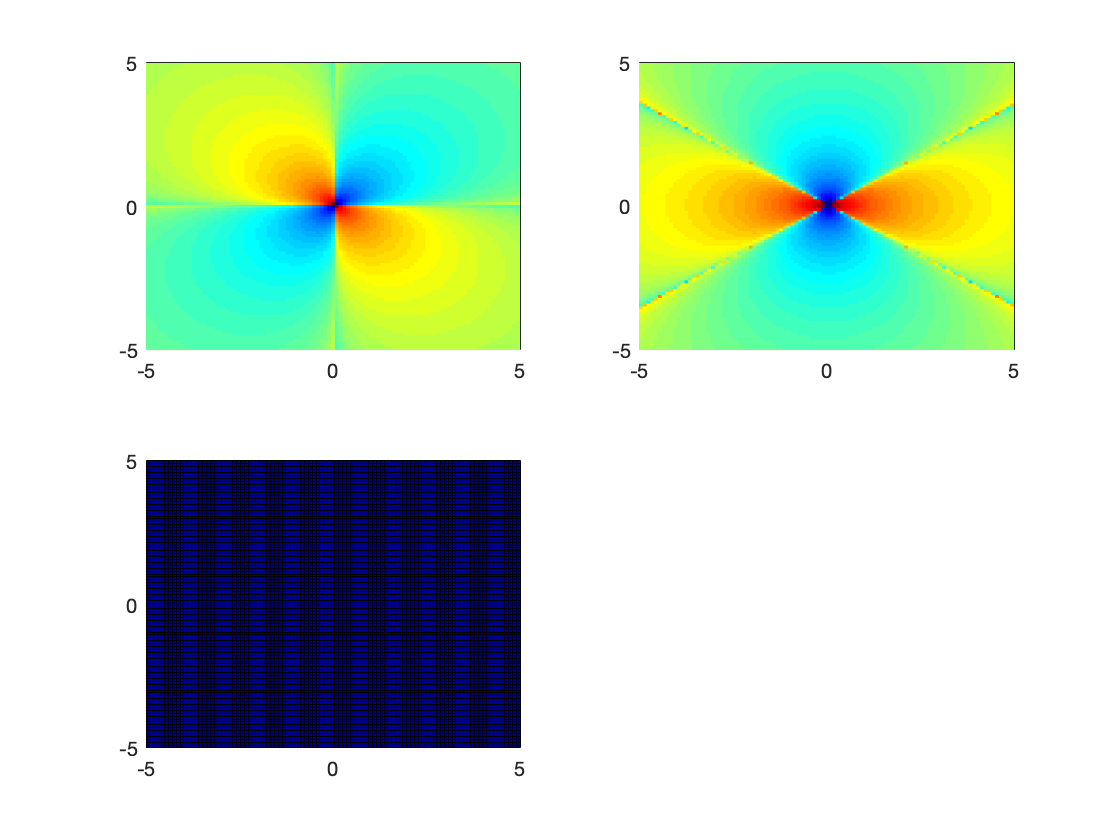

% 2D MESHGRIDS
x_arr_G = linspace(-5,5,100); 
y_arr_G = linspace(-5,5,100);
z_arr_G = linspace(-5,5,100);

% 2D PLANES!!!
[x2D_Gxy,y2D_Gxy] = meshgrid(x_arr_G,y_arr_G);
[x2D_Gxz,z2D_Gxz] = meshgrid(x_arr_G,z_arr_G);
[y2D_Gyz,z2D_Gyz] = meshgrid(y_arr_G,z_arr_G);

% array of zeros for unused dimension
zeros_arr = zeros(size(x2D_Gxy));

% calculating magnetic field
[B_gx2D,B_gy2D,B_gz2D] = magneticfield_xyz(zeros_arr,y2D_Gyz,z2D_Gyz,g0);

% plots ~ Y-Z PLANE
figure;
% y-z plane, B_gy2D
subplot(2,2,1);
pcolor(y2D_Gyz,z2D_Gyz,sign(B_gy2D).*log(abs(B_gy2D)))
colormap jet
shading flat

% y-z plane, B_gz2D
subplot(2,2,2);
pcolor(y2D_Gyz,z2D_Gyz,sign(B_gz2D).*log(abs(B_gz2D)))
colormap jet
shading flat

% y-z plane, B_gx2D
subplot(2,2,3);
pcolor(y2D_Gyz,z2D_Gyz,log(abs(B_gx2D)))

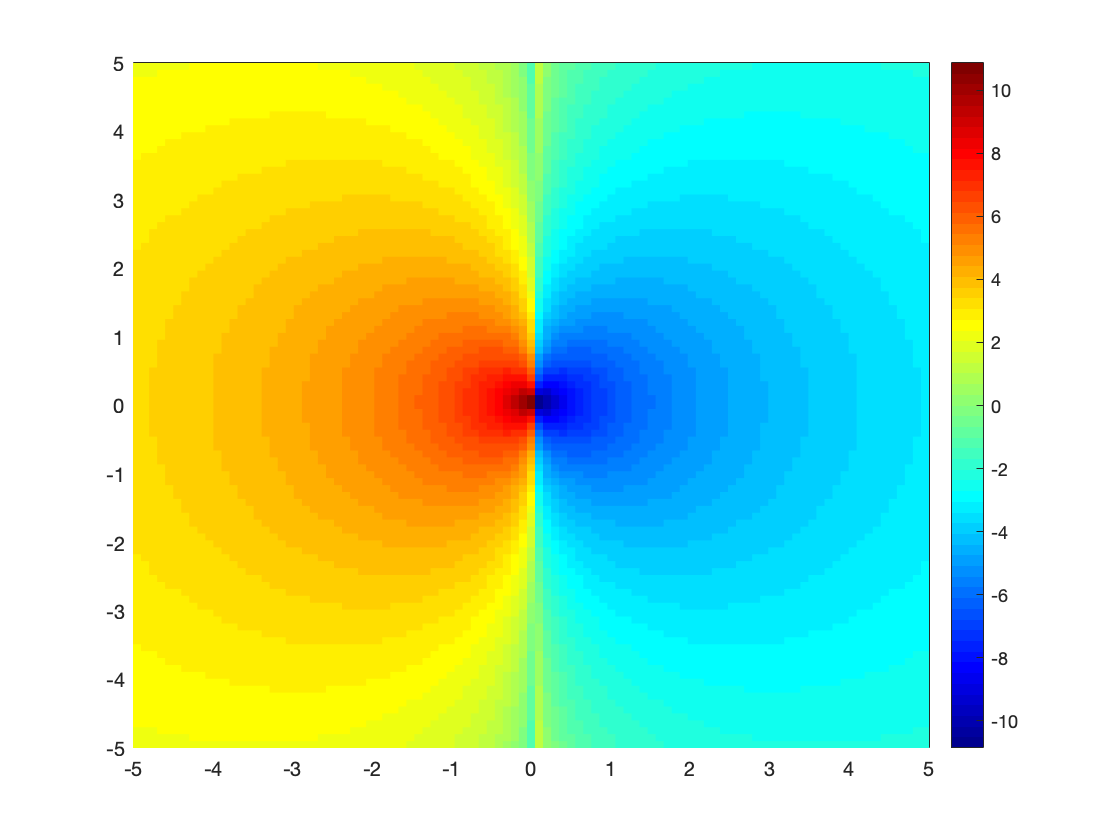

% pcolor plot of surface
figure;
u_yz = squeeze(potential_G(51,:,:));
% dipole potential plot of the y-z plane
pcolor(y2D_Gyz,z2D_Gyz,sign(u_yz).*log(abs(u_yz)))
colormap jet
colorbar
shading flat

### 2D Quiver Plots

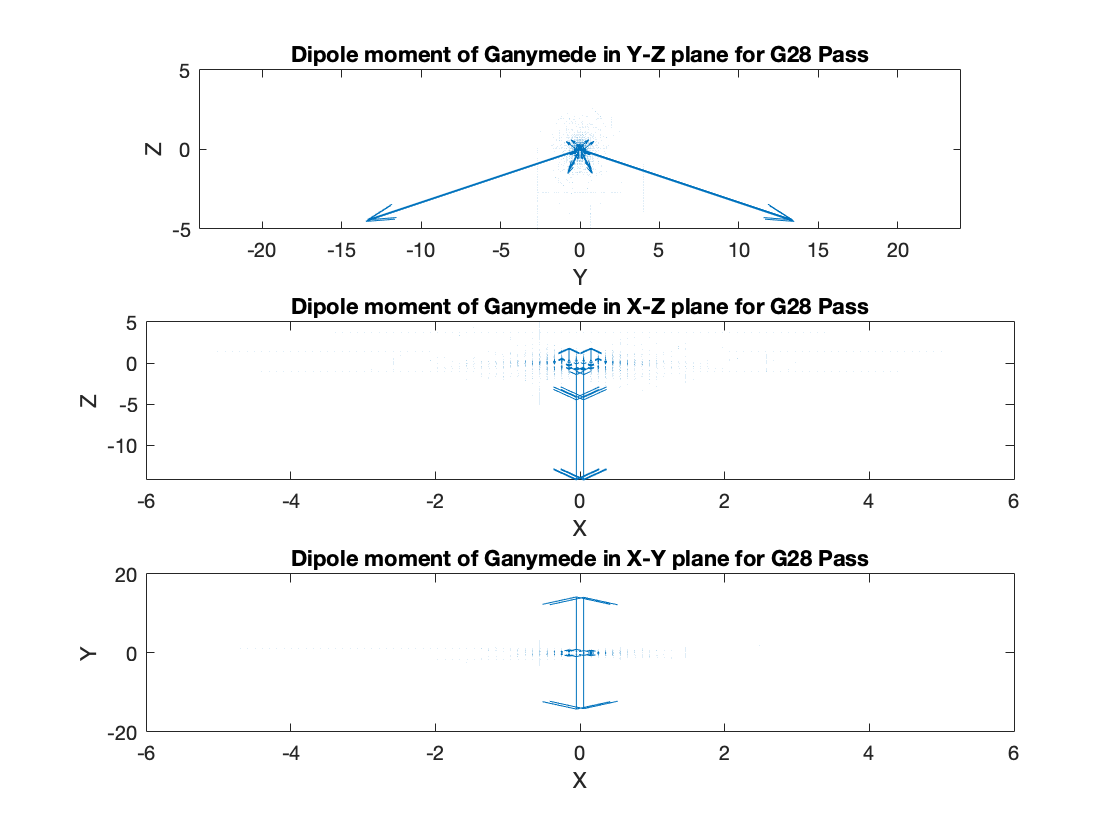

figure;
% Y-Z Plane
subplot(3,1,1);
quiver(y2D_Gyz,z2D_Gyz,B_gy2D,B_gz2D,100)
title('Dipole moment of Ganymede in Y-Z plane for G28 Pass',"Color",'k')
xlabel('Y')
ylabel('Z')
axis equal
% X-Z Plane
subplot(3,1,2);
quiver(x2D_Gxz,z2D_Gxz,B_gx2D,B_gz2D,100)
title('Dipole moment of Ganymede in X-Z plane for G28 Pass',"Color",'k')
xlabel('X')
ylabel('Z')
% X-Y Plane
subplot(3,1,3);
quiver(x2D_Gxy,y2D_Gxy,B_gx2D,B_gy2D,100)
title('Dipole moment of Ganymede in X-Y plane for G28 Pass',"Color",'k')
xlabel('X')
ylabel('Y')

### 2D Streamline Plots

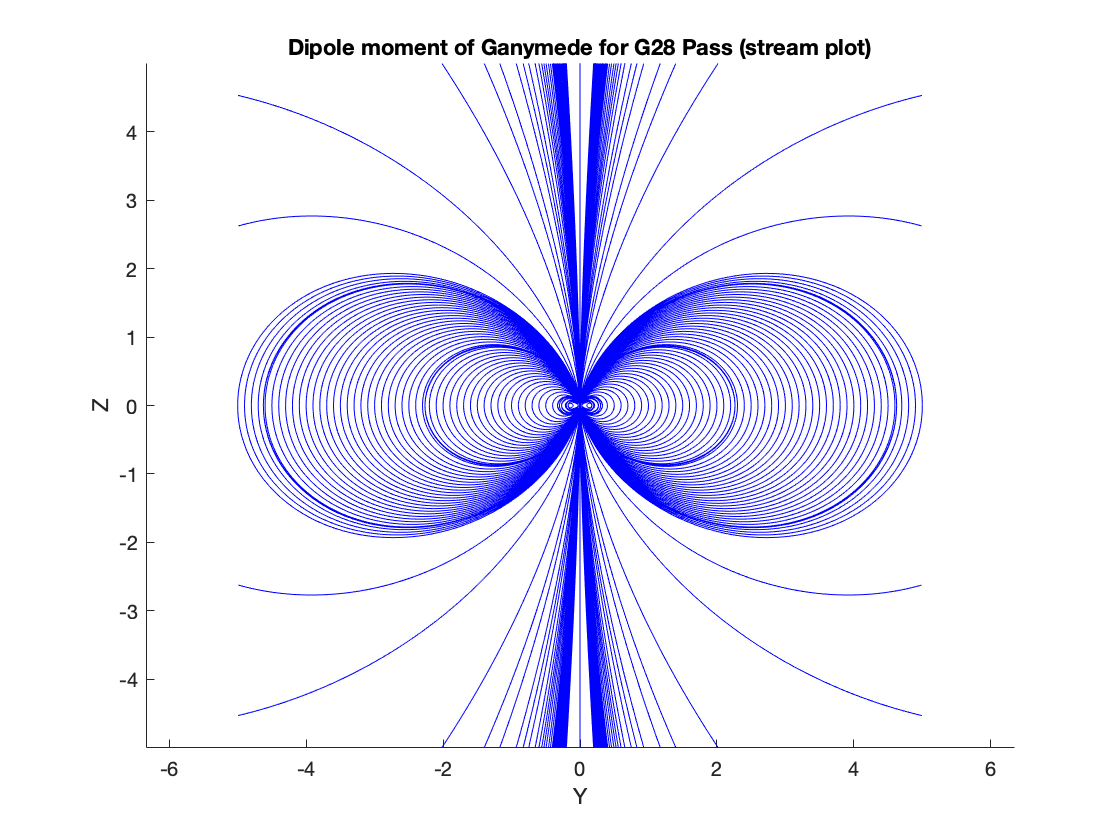

% Y-Z Plane
figure;
hold on
streamline(y2D_Gyz,z2D_Gyz,B_gy2D,B_gz2D,-5:0.1:5,zeros([1,101]))
streamline(y2D_Gyz,z2D_Gyz,-B_gy2D,-B_gz2D,-5:0.1:5,zeros([1,101]))
axis equal
hold off
title('Dipole moment of Ganymede for G28 Pass (stream plot)',"Color",'k')
xlabel('Y')
ylabel('Z')

### 3D plot - quiver3 + streamline + 3D view

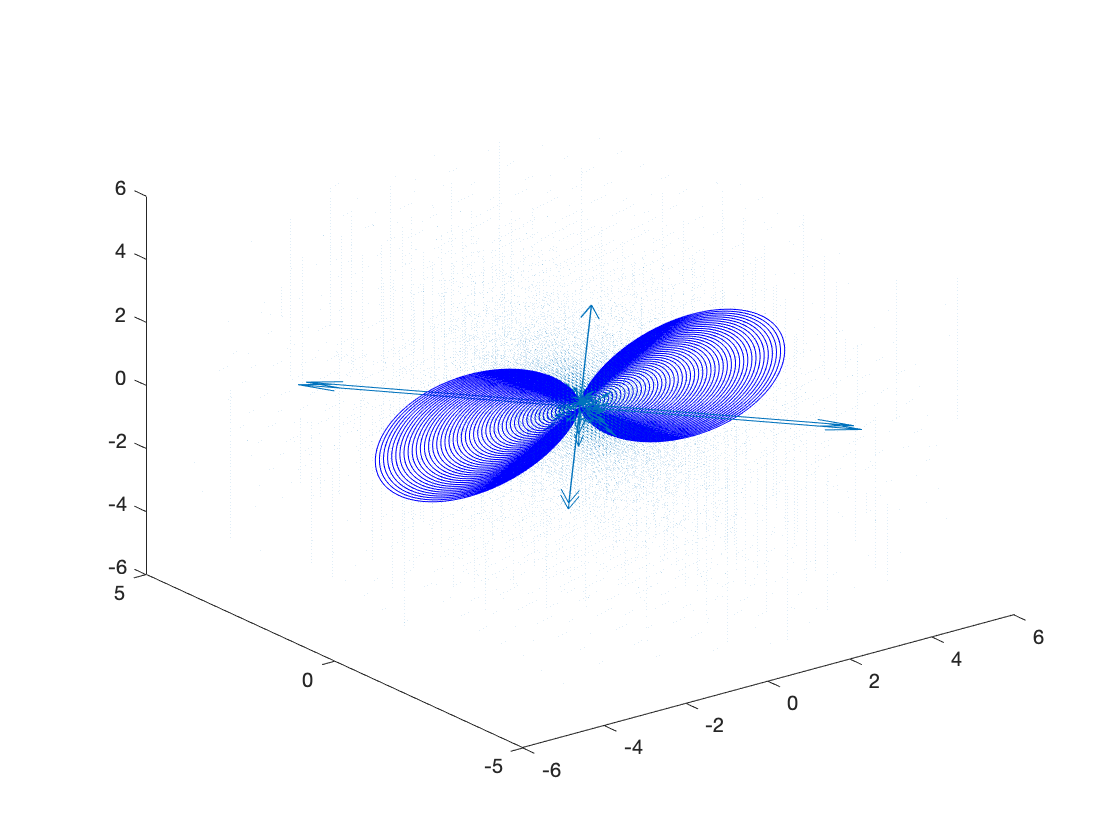

[B_gx,B_gy,B_gz] = magneticfield_xyz(x3D_G,y3D_G,z3D_G,g0);
startx = -5:0.1:5;
starty = zeros([1,101]);
startz = zeros([1,101]);
figure;
subplot(1,1,1);
hold on
quiver3(x3D_G,y3D_G,z3D_G,B_gx,B_gy,B_gz,50)
streamline(stream3(x3D_G,y3D_G,z3D_G,B_gx,B_gy,B_gz,startx,starty,startz))
streamline(stream3(x3D_G,y3D_G,z3D_G,-B_gx,-B_gy,-B_gz,startx,starty,startz))
view(3)
hold off

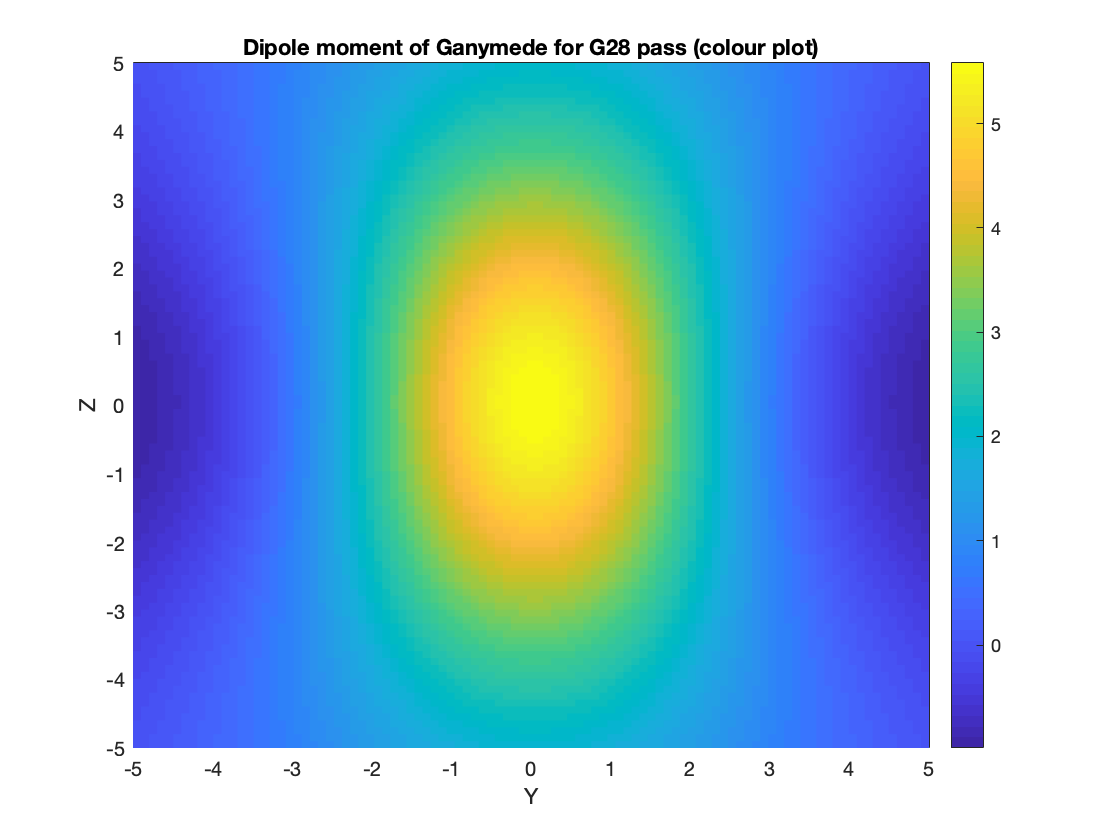

% plot in the y-z plane of the magnetic field
B_yz_2D = squeeze(B_gz(1,:,:));
figure;
pcolor(y2D_Gyz,z2D_Gyz,B_yz_2D)
colorbar
shading flat
title('Dipole moment of Ganymede for G28 pass (colour plot)',"Color",'k')
xlabel('Y')
ylabel('Z')

# Adding External Field from Jupiter

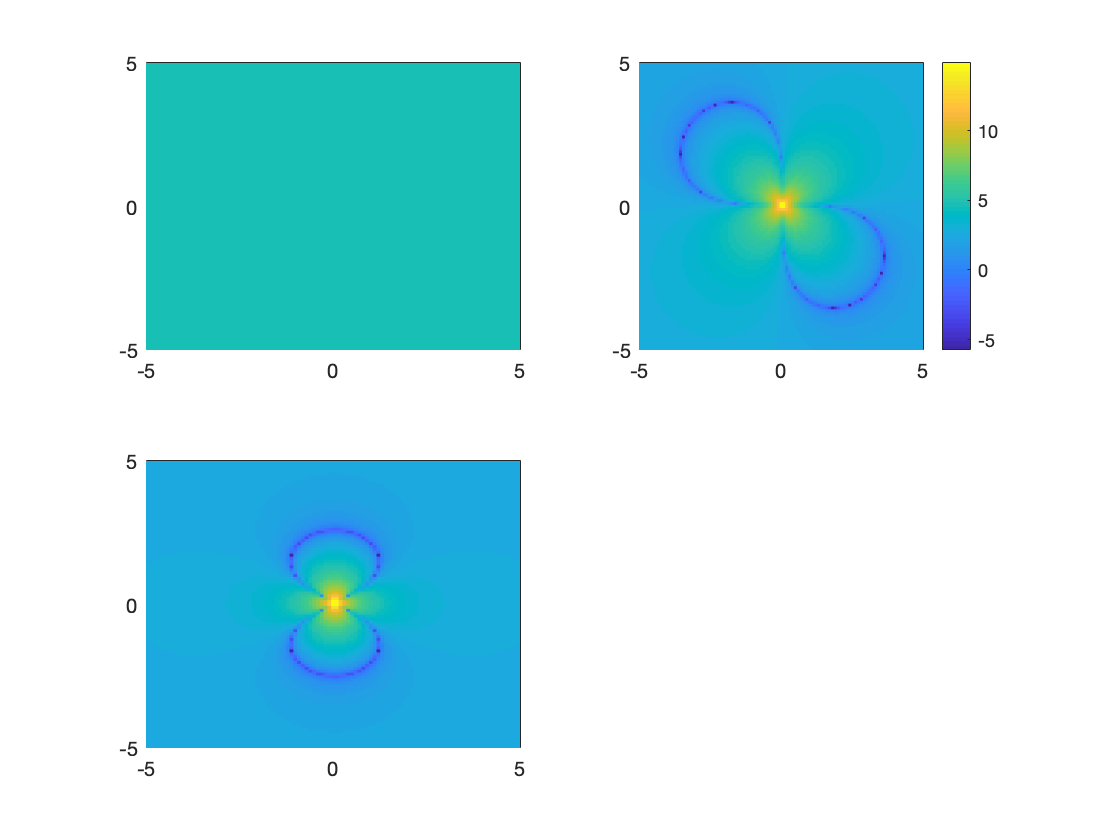

UFX = 34;
UFY = -13;
UFZ = 85;
B_JG_x = B_gx2D + UFX;
B_JG_y = B_gy2D + UFY;
B_JG_z = B_gz2D + UFZ;

% plots ~ Y-Z PLANE
figure;
% y-z plane, B_gy2D
subplot(2,2,1);
pcolor(y2D_Gyz,z2D_Gyz,log(abs(B_JG_x)))
shading flat

% y-z plane, B_gz2D
subplot(2,2,2);
pcolor(y2D_Gyz,z2D_Gyz,log(abs(B_JG_y)))
colorbar
shading flat

% y-z plane, B_gx2D
subplot(2,2,3);
pcolor(y2D_Gyz,z2D_Gyz,log(abs(B_JG_z)))
shading flat

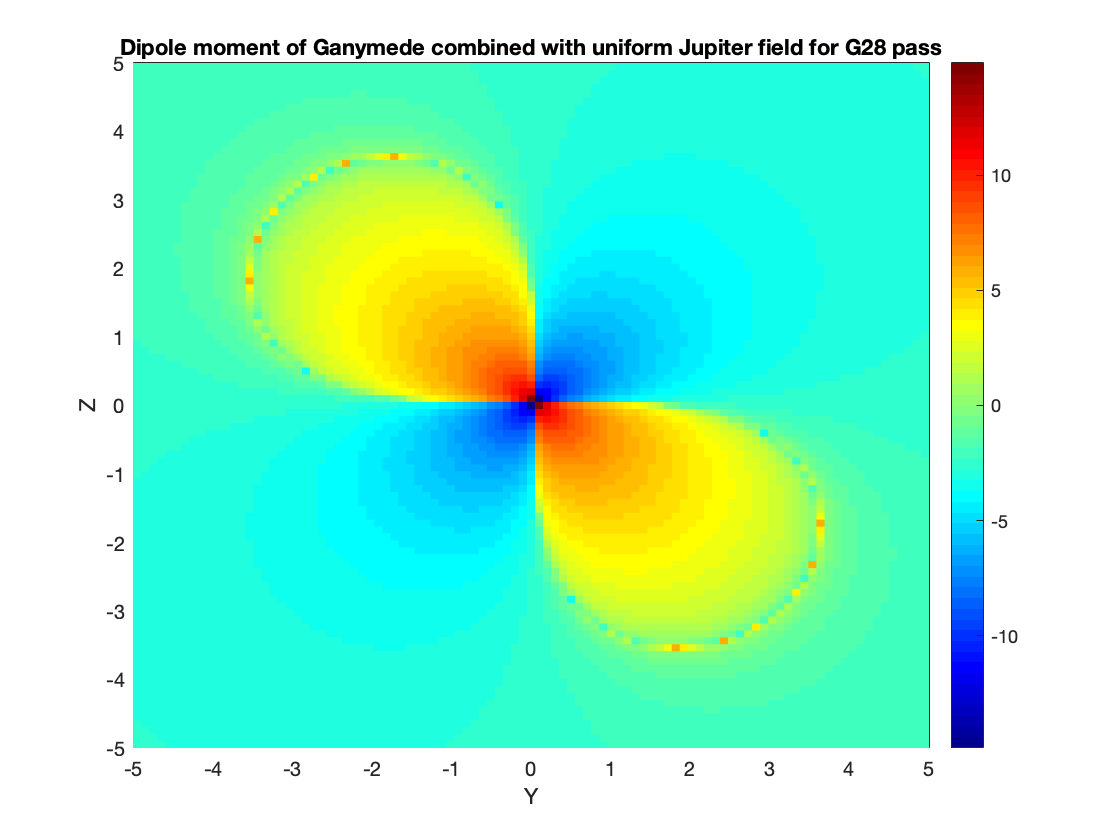

%% larger plot 
% y-z plane, B_gz2D
figure;
pcolor(y2D_Gyz,z2D_Gyz,sign(B_JG_y).*log(abs(B_JG_y)))
colormap jet
colorbar
shading flat
title('Dipole moment of Ganymede combined with uniform Jupiter field for G28 pass',"Color",'k')
xlabel('Y')
ylabel('Z')

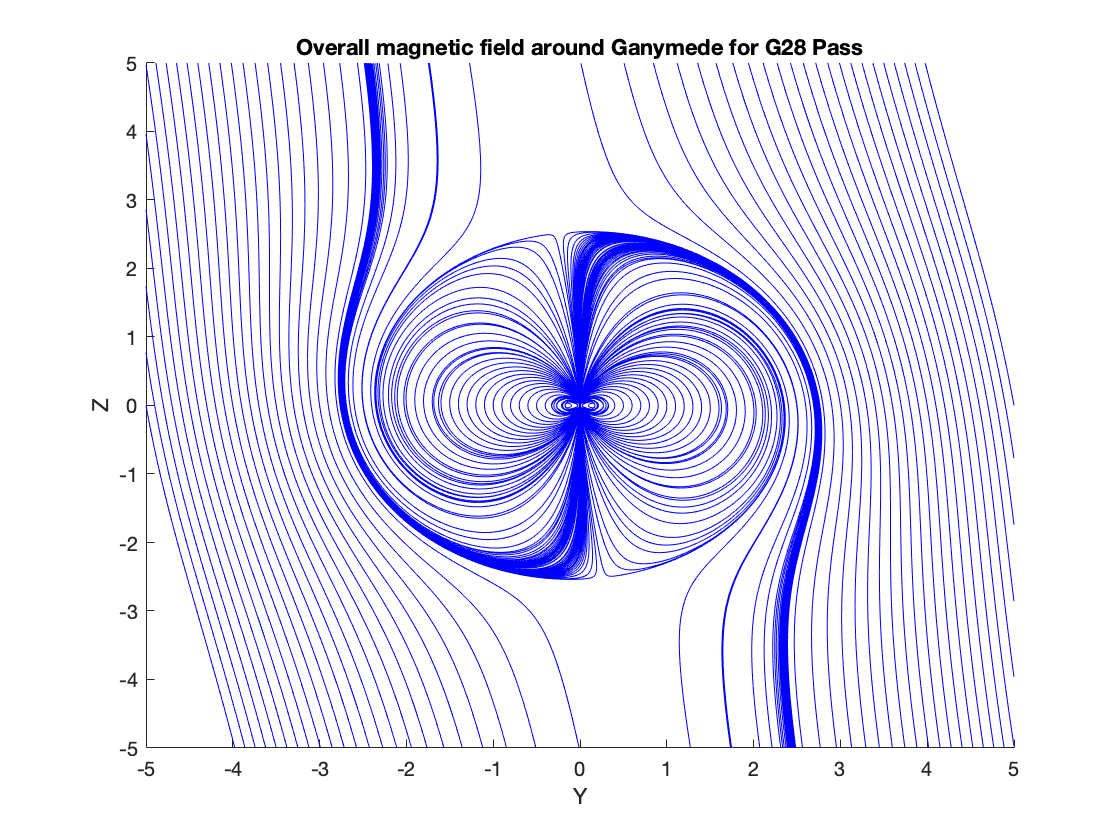

figure;
hold on
streamline(y2D_Gyz,z2D_Gyz,B_JG_y,B_JG_z,-5:0.1:5,zeros([1 101]))
streamline(y2D_Gyz,z2D_Gyz,-B_JG_y,-B_JG_z,-5:0.1:5,zeros([1 101]))
title('Overall magnetic field around Ganymede for G28 Pass',"Color",'k')
xlabel('Y')
ylabel('Z')
hold off

# All passes G1,G2,G7,G8,G28

g_1_0 = [-673 -728 -781 -549 -698]; % expansion constant for different passes
UFX_n = [-63 -62 -38 -36 34]; % x-component of external uniform field for different passes
UFY_n = [26 21 -13 -4 -13]; % y-component of external uniform field for different passes
UFZ_n = [12 15 5 126 85]; % z-component of external uniform field for different passes

% 3D grid
x_arr_G = linspace(-5,5,100);
y_arr_G = linspace(-5,5,100);
z_arr_G = linspace(-5,5,100);;

[y2D_Gyz,z2D_Gyz] = meshgrid(y_arr_G,z_arr_G); % 2D grid Y-Z plane for plots

% array of zeros for unused dimension
zeros_arr = zeros(size(x2D_Gxy));

# G1 Pass

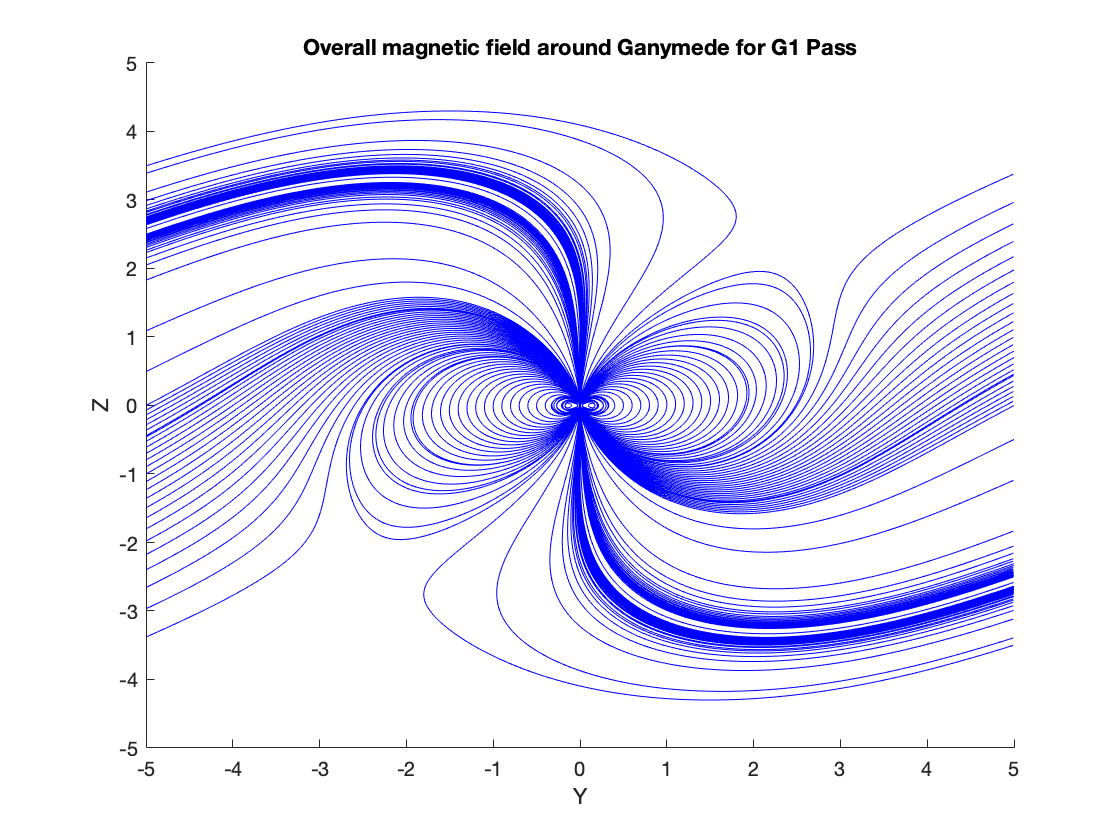

figure;
hold on
[Bx,By,Bz] = net_field(zeros_arr,y2D_Gyz,z2D_Gyz,g_1_0(1),UFX_n(1),UFY_n(1),UFZ_n(1));
streamline(y2D_Gyz,z2D_Gyz,By,Bz,-5:0.1:5,zeros([1 101]))
streamline(y2D_Gyz,z2D_Gyz,-By,-Bz,-5:0.1:5,zeros([1 101]))
title('Overall magnetic field around Ganymede for G1 Pass',"Color",'k')
xlabel('Y')
ylabel('Z')
hold off

# G2 Pass

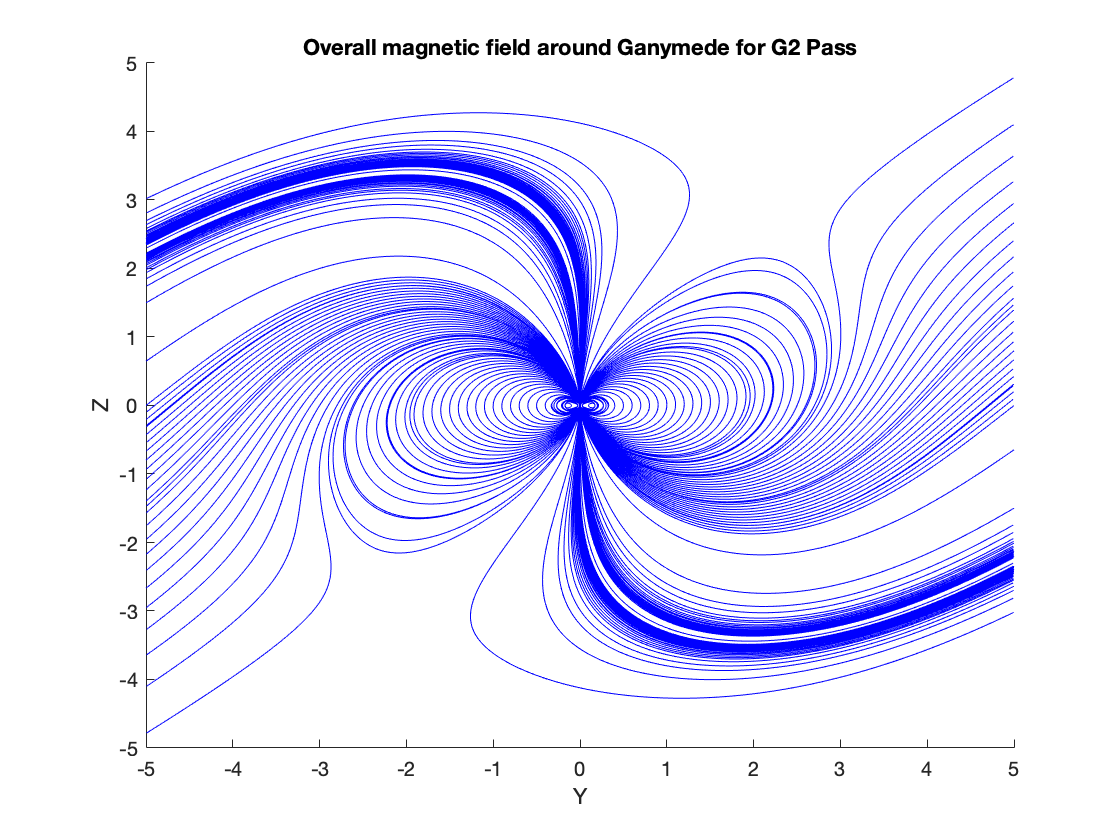

figure;
hold on
[Bx,By,Bz] = net_field(zeros_arr,y2D_Gyz,z2D_Gyz,g_1_0(2),UFX_n(2),UFY_n(2),UFZ_n(2));
streamline(y2D_Gyz,z2D_Gyz,By,Bz,-5:0.1:5,zeros([1 101]))
streamline(y2D_Gyz,z2D_Gyz,-By,-Bz,-5:0.1:5,zeros([1 101]))
title('Overall magnetic field around Ganymede for G2 Pass',"Color",'k')
xlabel('Y')
ylabel('Z')
hold off

# G7 Pass

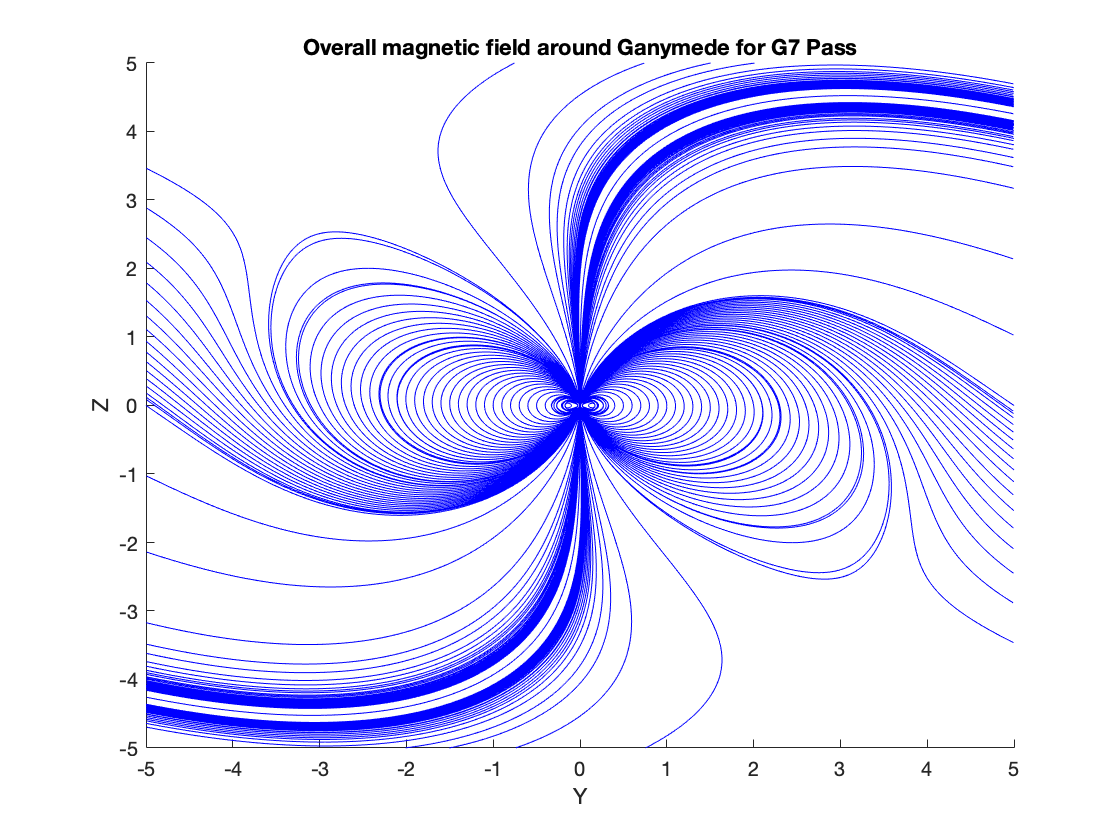

figure;
hold on
[Bx,By,Bz] = net_field(zeros_arr,y2D_Gyz,z2D_Gyz,g_1_0(3),UFX_n(3),UFY_n(3),UFZ_n(3));
streamline(y2D_Gyz,z2D_Gyz,By,Bz,-5:0.1:5,zeros([1 101]))
streamline(y2D_Gyz,z2D_Gyz,-By,-Bz,-5:0.1:5,zeros([1 101]))
title('Overall magnetic field around Ganymede for G7 Pass',"Color",'k')
xlabel('Y')
ylabel('Z')
hold off

# G8 Pass

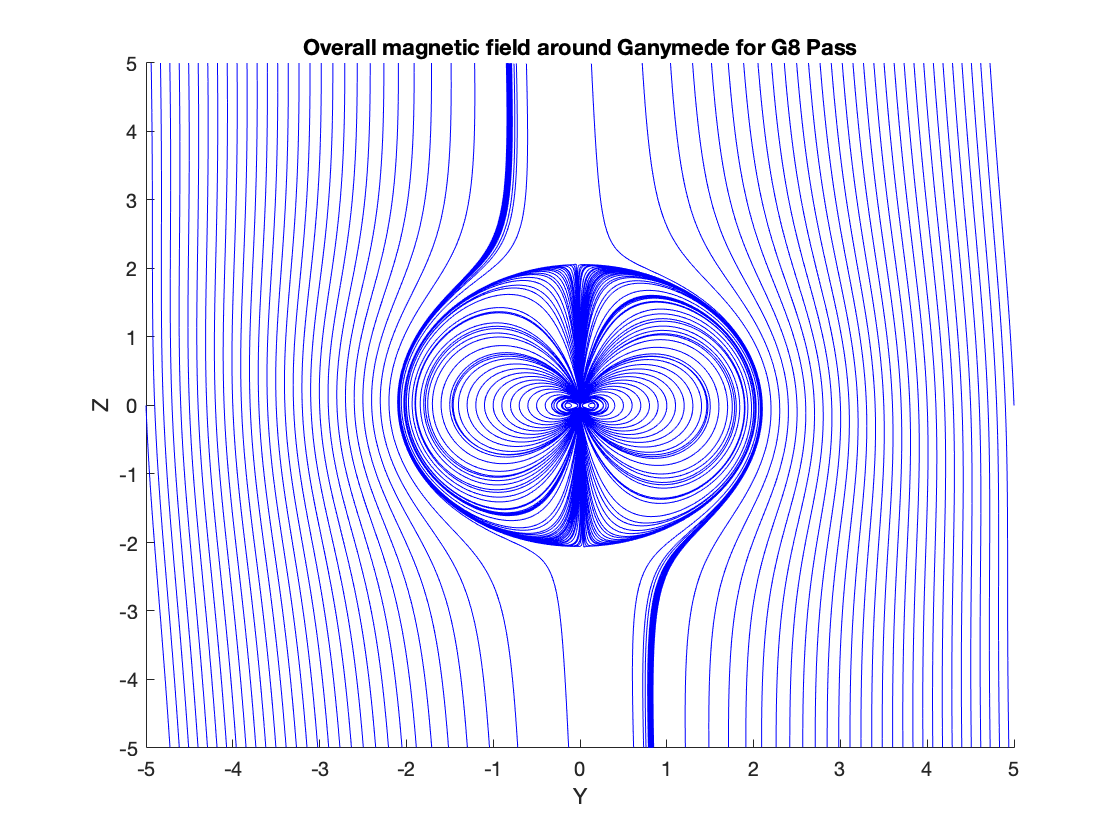

figure;
hold on
[Bx,By,Bz] = net_field(zeros_arr,y2D_Gyz,z2D_Gyz,g_1_0(4),UFX_n(4),UFY_n(4),UFZ_n(4));
streamline(y2D_Gyz,z2D_Gyz,By,Bz,-5:0.1:5,zeros([1 101]))
streamline(y2D_Gyz,z2D_Gyz,-By,-Bz,-5:0.1:5,zeros([1 101]))
title('Overall magnetic field around Ganymede for G8 Pass',"Color",'k')
xlabel('Y')
ylabel('Z')
hold off

# G28 Pass

figure;
hold on
[Bx,By,Bz] = net_field(zeros_arr,y2D_Gyz,z2D_Gyz,g_1_0(5),UFX_n(5),UFY_n(5),UFZ_n(5));
streamline(y2D_Gyz,z2D_Gyz,By,Bz,-5:0.1:5,zeros([1 101]))
streamline(y2D_Gyz,z2D_Gyz,-By,-Bz,-5:0.1:5,zeros([1 101]))
title('Overall magnetic field around Ganymede for G28 Pass',"Color",'k')
xlabel('Y')
ylabel('Z')
hold off

# Next part of the project: Circular trajectory of a spacecraft around Ganymede

## Approach

Equations of circular motion are used. 


$${\mathit{\mathbf{F}}}_s =\frac{{m_s v}^2 }{r_{\mathrm{tot}} }\hat{\mathit{\mathbf{r}}}$$


The spacecraft orbits Ganymede due to gravitational attraction given by Newton's inverse-square law formula:


$${\mathit{\mathbf{F}}}_s =\frac{{\mathrm{GM}}_g m_s }{r_{\mathrm{ror}}^2 }\hat{\mathit{\mathbf{r}}}$$


The aim is to plot the circular trajectory. 

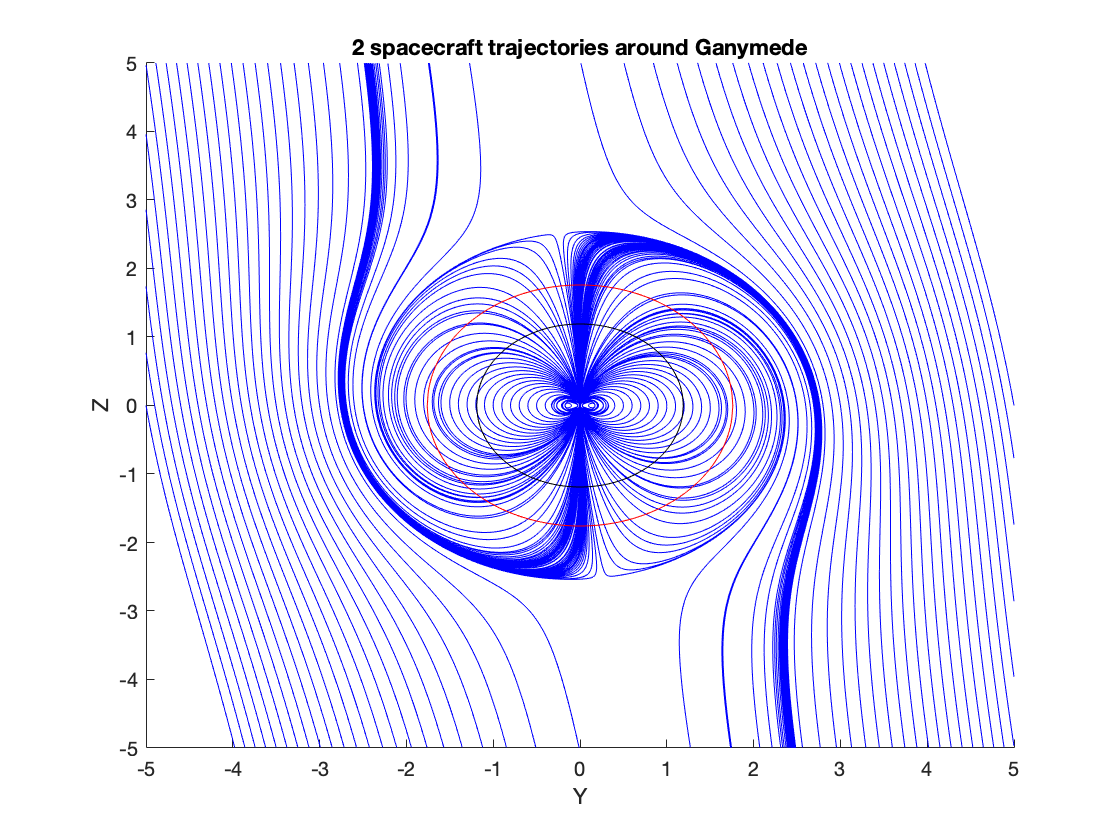

% two circular paths of different radii
r1 = 500; %km
r2 = 2000; %km

rG = 2634.1; %km

y_arr_G = linspace(-5,5,100);; % y-axis array
z_arr_G = linspace(-5,5,100);; % z-axis array

% trajectory 1
rpos1 = 1 + (r1/rG);
ypoints1 = (-rpos1:0.01:rpos1+0.01);
zpoints1 = real(sqrt(rpos1*rpos1 - ypoints1.*ypoints1));
circ1y = [ypoints1,-ypoints1(2:end)]; 
circ1z = [zpoints1,-zpoints1(2:end)];

% trajectory 2
rpos2 = 1 + (r2/rG);
ypoints2 = (-rpos2:0.01:rpos2+0.01);
zpoints2 = real(sqrt(rpos2*rpos2 - ypoints2.*ypoints2));
circ2y = [ypoints2,-ypoints2(2:end)];
circ2z = [zpoints2,-zpoints2(2:end)];

figure;
hold on
[Bx,By,Bz] = net_field(zeros_arr,y2D_Gyz,z2D_Gyz,g_1_0(5),UFX_n(5),UFY_n(5),UFZ_n(5));
streamline(y2D_Gyz,z2D_Gyz,By,Bz,-5:0.1:5,zeros([1 101]))
streamline(y2D_Gyz,z2D_Gyz,-By,-Bz,-5:0.1:5,zeros([1 101]))
plot(circ1y,circ1z,'k-')
plot(circ2y,circ2z,'r-')
title('2 spacecraft trajectories around Ganymede',"Color",'k')
xlabel('Y')
ylabel('Z')

Extracting points on the trajectories

% Extracting B_y and B_z
By_circ1 = interp2(y2D_Gyz,z2D_Gyz,By,circ1y,circ1z);
Bz_circ1 = interp2(y2D_Gyz,z2D_Gyz,Bz,circ1y,circ1z);
By_circ2 = interp2(y2D_Gyz,z2D_Gyz,By,circ2y,circ2z);
Bz_circ2 = interp2(y2D_Gyz,z2D_Gyz,Bz,circ2y,circ2z);

## By for 2 orbits

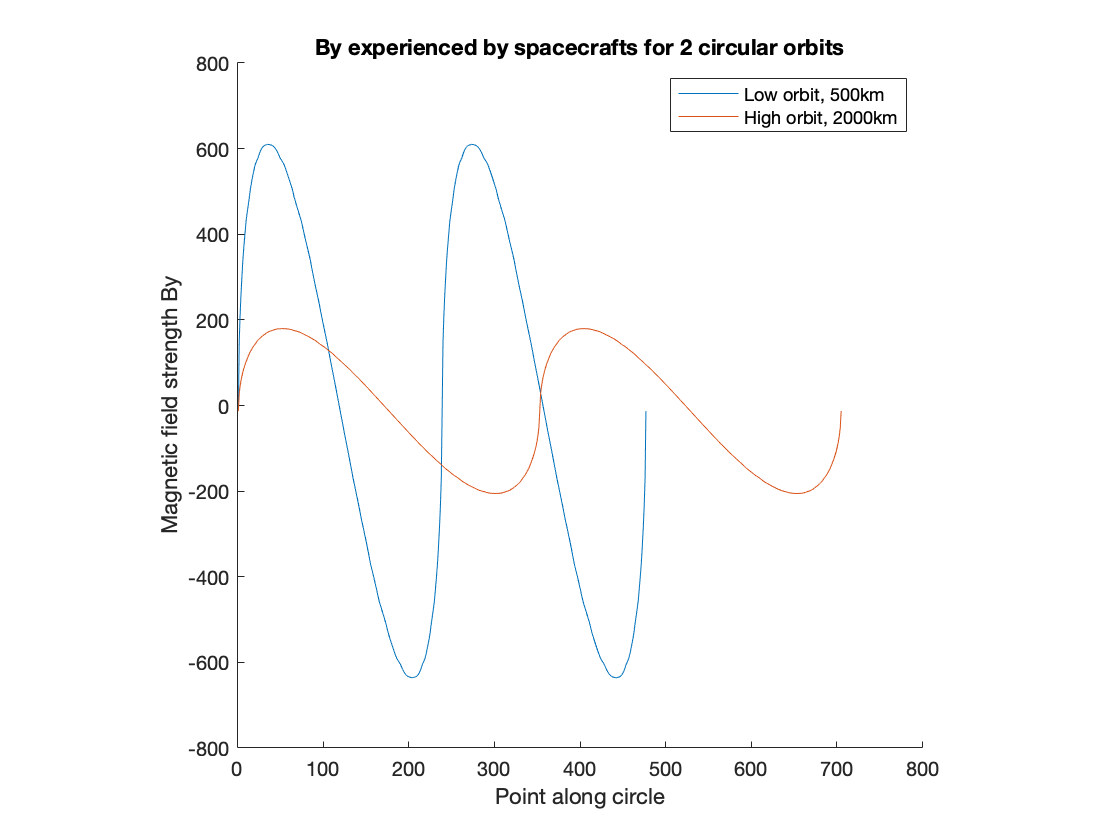

figure;
hold on
plot(By_circ1)
plot(By_circ2)
legend('Low orbit, 500km','High orbit, 2000km')
pbaspect([1 1 1])
title('By experienced by spacecrafts for 2 circular orbits')
xlabel('Point along circle')
ylabel('Magnetic field strength By')

## Bz for 2 orbits

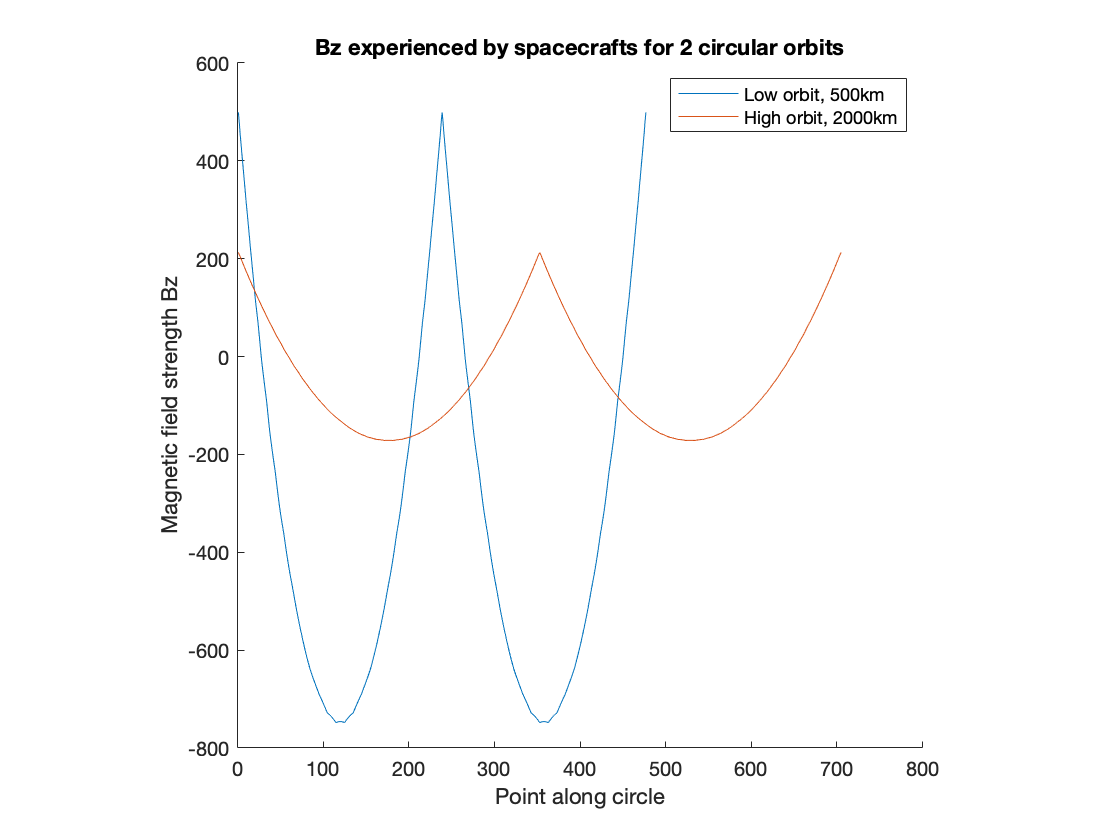

figure;
hold on
plot(Bz_circ1)
plot(Bz_circ2)
legend('Low orbit, 500km','High orbit, 2000km')
pbaspect([1 1 1])
title('Bz experienced by spacecrafts for 2 circular orbits')
xlabel('Point along circle')
ylabel('Magnetic field strength Bz')

## Bx for 2 orbits

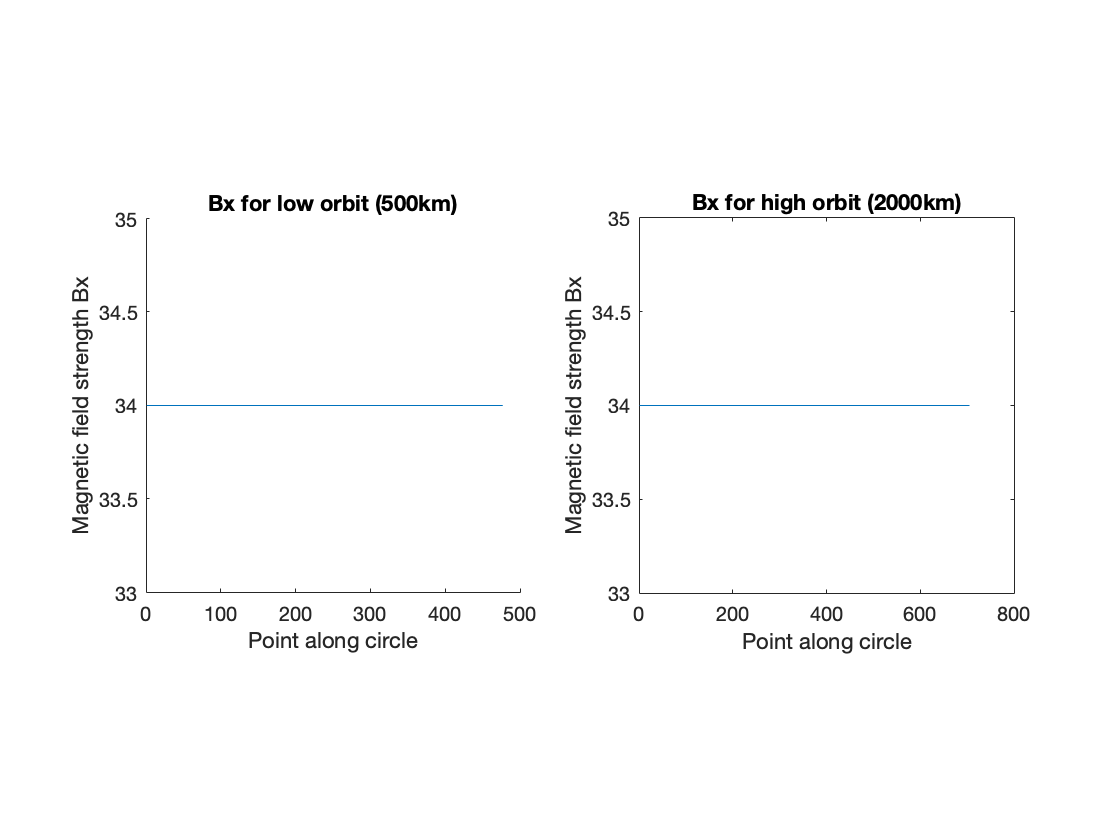

Bx_circ1 = interp2(y2D_Gyz,z2D_Gyz,Bx,circ1y,circ1z);
Bx_circ2 = interp2(y2D_Gyz,z2D_Gyz,Bx,circ2y,circ2z);

figure;
subplot(1,2,1);
hold on
plot(Bx_circ1)
pbaspect([1 1 1])
title('Bx for low orbit (500km)')
xlabel('Point along circle')
ylabel('Magnetic field strength Bx')
subplot(1,2,2);
plot(Bx_circ2)
pbaspect([1 1 1])
title('Bx for high orbit (2000km)')
xlabel('Point along circle')
ylabel('Magnetic field strength Bx')

**Comment:** In the X direction the spacecrafts are only affected by the external Jupiter field, which has a uniform magnitude spatially (within the scale of Ganymede radius). 

# Investigating the X-Y Plane

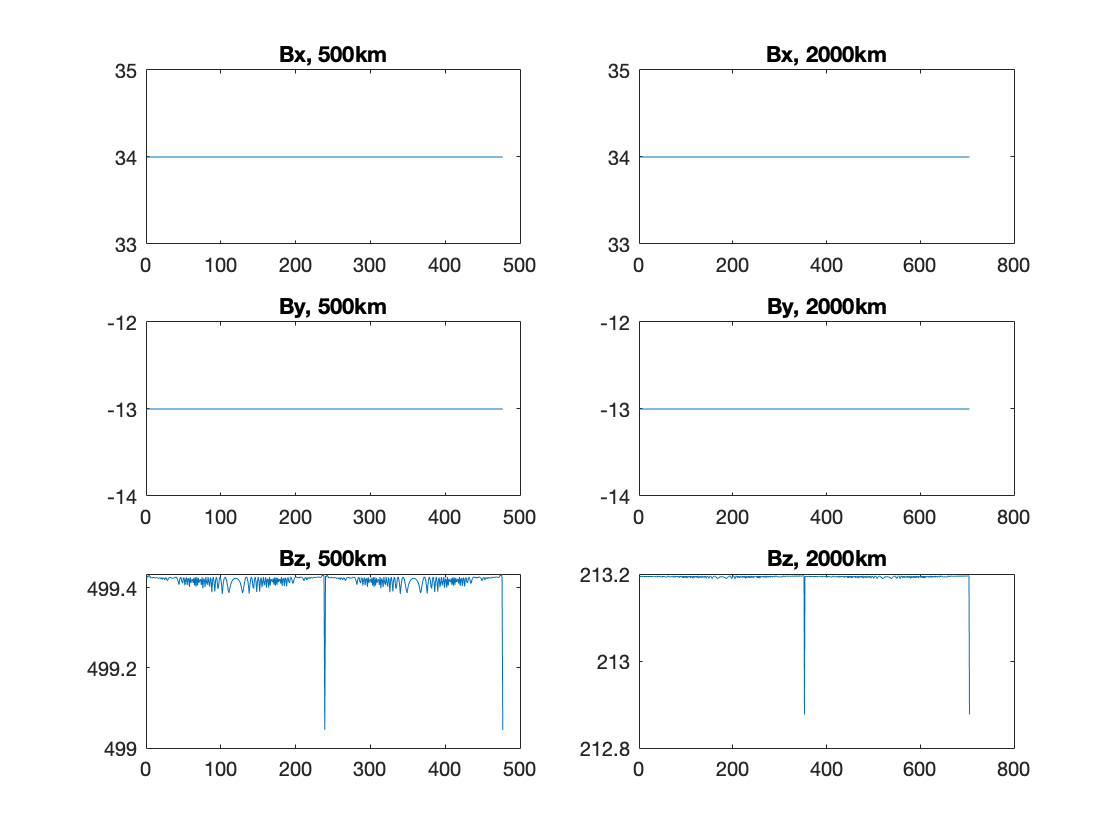

x_arr_G = linspace(-5,5,1000);; 
y_arr_G = linspace(-5,5,1000);;

[x2D_Gxy,y2D_Gxy] = meshgrid(x_arr_G,y_arr_G);

zeros_arr = zeros(size(x2D_Gxy));

[Bx,By,Bz] = net_field(x2D_Gxy,y2D_Gxy,zeros_arr,g_1_0(5),UFX_n(5),UFY_n(5),UFZ_n(5));

% trajectory 1
rpos1 = 1 + (r1/rG);
xpoints1 = (-rpos1:0.01:rpos1+0.01);
ypoints1 = real(sqrt(rpos1*rpos1 - xpoints1.*xpoints1));
circ1x = [xpoints1,-xpoints1(2:end)]; 
circ1y = [ypoints1,-ypoints1(2:end)];

% trajectory 24
rpos2 = 1 + (r2/rG);
xpoints2 = (-rpos2:0.01:rpos2+0.01);
ypoints2 = real(sqrt(rpos2*rpos2 - xpoints2.*xpoints2));
circ2x = [xpoints2,-xpoints2(2:end)];
circ2y = [ypoints2,-ypoints2(2:end)];

% extracting bx, by and bz
% Orbit 1
Bx_circ1xy = interp2(x2D_Gxy,y2D_Gxy,Bx,circ1x,circ1y);
By_circ1xy = interp2(x2D_Gxy,y2D_Gxy,By,circ1x,circ1y);
Bz_circ1xy = interp2(x2D_Gxy,y2D_Gxy,Bz,circ1x,circ1y);
% Orbit 2
Bx_circ2xy = interp2(x2D_Gxy,y2D_Gxy,Bx,circ2x,circ2y);
By_circ2xy = interp2(x2D_Gxy,y2D_Gxy,By,circ2x,circ2y);
Bz_circ2xy = interp2(x2D_Gxy,y2D_Gxy,Bz,circ2x,circ2y);

% plotting
figure;
subplot(3,2,1);
plot(Bx_circ1xy)
title('Bx, 500km')
subplot(3,2,2);
plot(Bx_circ2xy)
title('Bx, 2000km')
subplot(3,2,3);
plot(By_circ1xy)
title('By, 500km')
subplot(3,2,4);
plot(By_circ2xy)
title('By, 2000km')
subplot(3,2,5);
plot(Bz_circ1xy)
title('Bz, 500km')
subplot(3,2,6);
plot(Bz_circ2xy)
title('Bz, 2000km')